syms s vin ia kw h th thp hp q0

ia=1;
kw=0.1;
C=1;
k=50;

thp=(1/kw)*(50*vin-10*ia);
hp=(1/C)*(80*th-k*sqrt(h));

q0=k*sqrt(h);

xe=[th,h]

$$xe = \left(\begin{array}{cc} \mathrm{th} & h \end{array}\right)$$


ts=1

ts = 1

zta=1

zta = 1


A=jacobian([thp,hp],xe)

$$A = \left(\begin{array}{cc} 0 & 0\\ 80 & -\frac{25}{\sqrt{h}} \end{array}\right)$$

B=jacobian([thp,hp],vin)

$$B = \left(\begin{array}{c} 500\\ 0 \end{array}\right)$$

C=jacobian(q0,xe)

$$C = \left(\begin{array}{cc} 0 & \frac{25}{\sqrt{h}} \end{array}\right)$$

D=jacobian(q0,vin)

$$D = 0$$

%%%%%%%%% P.op
h=1;
%%%%%%%%%
A=double(eval(A))

A =      0     0
    80   -25


B=double(eval(B))

B =    500
     0


C=double(eval(C))

C =      0    25


D=double(eval(D))

D = 0

[num,den]=ss2tf(A,B,C,D)

num =            0           0     1000000


den =      1    25     0


ft=tf(num,den)

ft =
 
     1e06
  ----------
  s^2 + 25 s
 
Continuous-time transfer function.



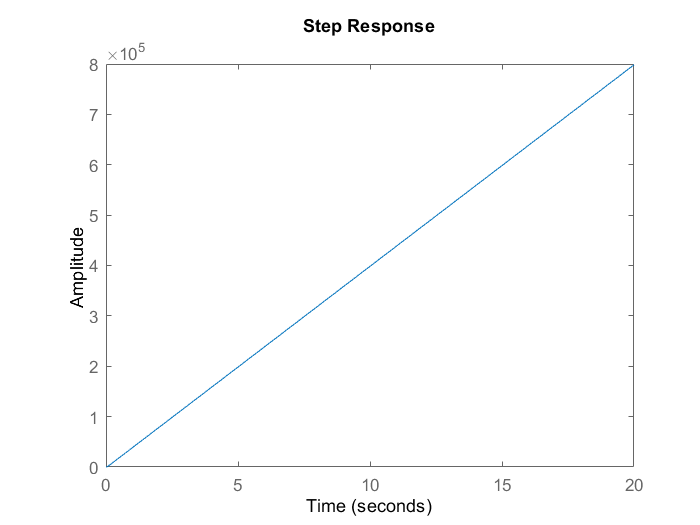

step(ft)

%%%%%%%%
wn=4/(ts*zta)

wn = 4

polos=roots([1 2*zta*wn wn^2])

polos =     -4
    -4


K=acker(A,B,polos)

K =    -0.0340    0.0110


%PARA ESS=0 RAMPA
polosEss=conv(polos,[1 5*wn*zta])

polosEss =     -4   -84   -80


polosEss=conv(polosEss,[1 5*wn*zta])

polosEss =           -4        -164       -1760       -1600


Aempaq=[A(1,1),A(1,2),0,0;A(2,1),A(2,2),0,0;0,0,0,1;-C(1,1),-C(1,2),0,0]

Aempaq =      0     0     0     0
    80   -25     0     0
     0     0     0     1
     0   -25     0     0


Bempaq=[B(1,1);B(2,1);0;0]

Bempaq =    500
     0
     0
     0


Cempaq=[C(1,1),C(1,2),0,0]

Cempaq =      0    25     0     0


K1=acker(Aempaq,Bempaq,polosEss)

K1 = 	1.0e+03 *

    0.0070    0.0823   -1.8473   -0.4753


%%%% Para Transport delay 0.1s
tm=0.1

tm = 0.1000

polosEssT=conv(polosEss,[1 5*wn*zta])

polosEssT =           -4        -244       -5040      -36800      -32000


polosEssT=conv(polosEssT,[1 5*wn*zta])

polosEssT =           -4        -324       -9920     -137600     -768000     -640000


ftdelay=tf([1],[(tm^2)/2 tm 1])

ftdelay =
 
            1
  ---------------------
  0.005 s^2 + 0.1 s + 1
 
Continuous-time transfer function.



ft2=ft*ftdelay

ft2 =
 
                   1e06
  --------------------------------------
  0.005 s^4 + 0.225 s^3 + 3.5 s^2 + 25 s
 
Continuous-time transfer function.



[A1,B1,C1,D1]=tf2ss(1e6,[0.005,0.225,3.5,25,0])

A1 =          -45        -700       -5000           0
           1           0           0           0
           0           1           0           0
           0           0           1           0


B1 =      1
     0
     0
     0


C1 =            0           0           0   200000000


D1 = 0

Aempaq1=[A1(1,1),A1(1,2),A1(1,3),A1(1,4),0,0;A1(2,1),A1(2,2),A1(2,3),A1(2,4),0,0;A1(3,1),A1(3,2),A1(3,3),A1(3,4),0,0;A1(4,1),A1(4,2),A1(4,3),A1(4,4),0,0;0,0,0,0,0,1;-C1(1,1),-C1(1,2),-C1(1,3),-C1(1,4),0,0]

Aempaq1 =          -45        -700       -5000           0           0           0
           1           0           0           0           0           0
           0           1           0           0           0           0
           0           0           1           0           0           0
           0           0           0           0           0           1
           0           0           0  -200000000           0           0


Bempaq1=[B1(1,1);B1(2,1);B1(3,1);B1(4,1);0;0]

Bempaq1 =      1
     0
     0
     0
     0
     0


KDelay=acker(Aempaq1,Bempaq1,polosEssT)

KDelay = 	1.0e+20 *

    0.0000    0.0000    0.0007    6.9534   -0.0000   -0.0000


## OBSERVADOR

tsa=ts/10;
wna=4/(tsa*zta)

wna = 40

obs=[C;C*A]

obs =            0          25
        2000        -625


det(obs)

ans = -50000

pdo=conv([1 2*tsa*zta wna^2],[1 10*wna*zta])

pdo = 	1.0e+05 *

    0.0000    0.0040    0.0168    6.4000


phia= A^3+pdo(2)*A^2+pdo(3)*A+pdo(4)*eye(2)

phia =       640000           0
     -616000      832500


L=phia*(inv(obs))*[1;0]

L =         8000
       25600
